load constants.mat;
velocities = 0:10:9000;
timespan = [0 10^7];
[max_heights, min_heights] = sweep(velocities, timespan);


## Verification

### Doesn't Go Through The Earth

First, we'll need to verify that, for all velocities, the object doesn't go through the Earth. This means that the object's distance from the origin should always be greater than the Earth's radius. We can see that is indeed the case:

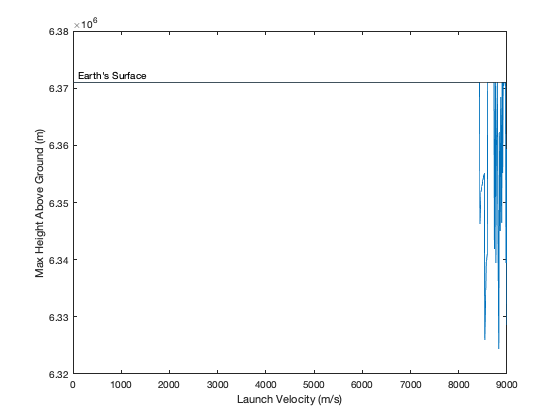

plot(velocities, min_heights);
yline(radius_earth)
ylabel("Max Height Above Ground (m)")
xlabel("Launch Velocity (m/s)")
text(100, radius_earth, "Earth's Surface", "VerticalAlignment", "bottom", "HorizontalAlignment", "left")

### Magnitude of Velocity Changes

Next, we need to make sure our velocity is obeying the trajectories we expect. In particular, we expect that the magnitude of velocity to be inverseley correlated with the magnitude of position: When the object is farthest from Earth, it will have the most gravitational potential energy. Since the total energy of the object can't change, it's kinetic energy (which is directly correlated with velocity) must shrink. Conversely, when the object is closest to the Earth, it's kinetic energy (and therefore velocity) will be at a maximum because the gravitational potential energy will be at a minimum.

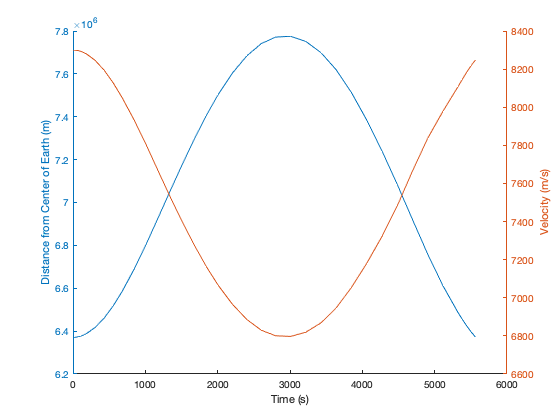

[T, P, V] = simulate_launch(timespan, [radius_earth + 1, 0, 0, 8300]);

clf; hold on;

yyaxis left;
plot(T, magnitude2d(P));
ylabel("Distance from Center of Earth (m)");

yyaxis right;
plot(T, magnitude2d(V));
ylabel("Velocity (m/s)");

xlabel("Time (s)");
hold off;

## Validation

Goes Here

## Results

### Velocity

We found that the minimum launch velocity required to achive orbital heights was 8000 m/s. Slighly higher velocities simply resulted in higher heights, while much higher velocities eventually exceeded the escape velocity of the Earth and resulted in the object flying off in to space (not shown on graph).

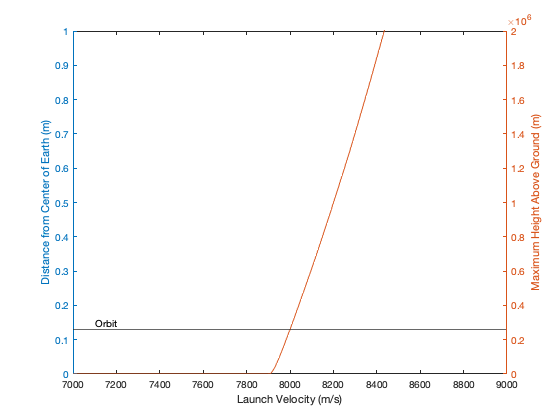

plot(velocities, max_heights - radius_earth);
yline(radius_orbit - radius_earth)
ylabel("Maximum Height Above Ground (m)")
xlabel("Launch Velocity (m/s)")
ylim([0 max_orbit_height])
x_lims = [7000, 9000];
xlim(x_lims)
text(x_lims(1) + 100, radius_orbit - radius_earth, "Orbit", "VerticalAlignment", "bottom", "HorizontalAlignment", "left")

### Maximum Energy

As expected, the maximum kinetic energy that an object acheived was strongly correlated with the maximum height that it reached. 

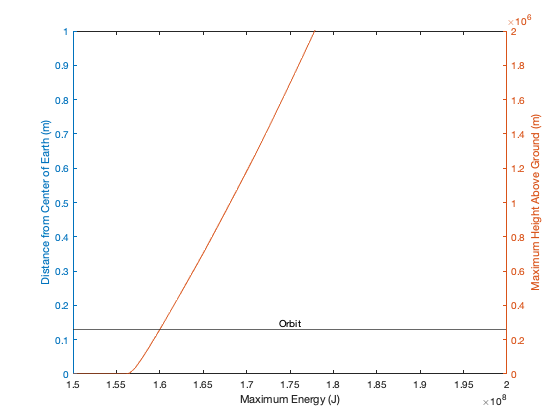

plot(0.5 * mass * (velocities .^ 2), max_heights - radius_earth);
yline(radius_orbit - radius_earth)
ylabel("Maximum Height Above Ground (m)")
xlabel("Maximum Energy (J)")
ylim([0 max_orbit_height])
x_lims = [150000000, 200000000];
xlim(x_lims)
text(mean(x_lims), radius_orbit - radius_earth, "Orbit", "VerticalAlignment", "bottom", "HorizontalAlignment", "center")

## Interpretation

## Things to Talk About:

- Mach numbers for velocities

- How circularizing would work

function res = magnitude2d(dat)
    res = sqrt(sum(dat .^ 2, 2));
end